%% SLP SU VOLTI (senza SVD)
% Questo script addestra un Single-Layer Perceptron (SLP) direttamente
% sui pixel (centrati) dei volti, eliminando completamente la fase SVD.

clear; clc; close all;

%% Impostazioni percorso
projectRoot = '/Users/giuseppebonomo/Desktop/UNIPA CdLM Ing_Informatica/.../ProgettoMetodi';
addpath(genpath(projectRoot));

%% Crea cartella risultati (se non esiste)
this_folder  = pwd;
results_path = fullfile(this_folder,'results');
if ~exist(results_path,'dir')
    mkdir(results_path);
    fprintf('>>> Creo la cartella results\n');
end

%% 1) Caricamento dataset
fprintf('>>> Caricamento dataset...\n');

>>> Caricamento dataset...


tic;
load('dataset/volti_dataset.mat','A','labels');  % A (m×n), labels
fprintf('   fatto in %.2f s\n', toc);

   fatto in 0.04 s



[m, n] = size(A);
img_h = 112; img_w = 92;        % dimensioni immagini

%% 2) Calcolo e salvataggio volto medio (opzionale)
fprintf('>>> Calcolo volto medio...\n');

>>> Calcolo volto medio...


tic;
mean_face = mean(A,2);          % [m×1]
save(fullfile(results_path,'mean_face.mat'),'mean_face');
fprintf('   fatto in %.2f s\n', toc);

   fatto in 0.01 s



%% 3) Centratura dati
fprintf('>>> Centratura dati...\n');

>>> Centratura dati...


tic;
A_centered = A - mean_face;     % [m×n]
fprintf('   fatto in %.2f s\n', toc);

   fatto in 0.00 s



%% 4) Prepara X e y per SLP
X           = A_centered';      % [n_samples × input_dim]
y           = labels(:);        % [n_samples × 1]
num_classes = max(y);

%% 5) Split train/test (7 immagini per soggetto per train)
train_idx = []; test_idx = [];
for s = 1:num_classes
    idx = find(y==s);
    idx = idx(randperm(numel(idx)));
    train_idx = [train_idx; idx(1:7)];
    test_idx  = [test_idx;  idx(8:end)];
end

X_train = X(train_idx, :);      % [n_train × input_dim]
y_train = y(train_idx);         % [n_train × 1]
X_test  = X(test_idx,  :);      % [n_test  × input_dim]
y_test  = y(test_idx);          % [n_test  × 1]

%% 6) One-hot encoding per cross-entropy
Y_train = zeros(num_classes, numel(y_train));
for i = 1:numel(y_train)
    Y_train(y_train(i), i) = 1;
end

%% 7) Iperparametri SLP
epochs        = 100;
learning_rate = 0.005;

%% 8) Addestramento SLP tramite Gradient Descent
fprintf('>>> Addestramento SLP...\n');

>>> Addestramento SLP...


tic;
[W, b, loss_slp] = slp_gradient_descent(X_train, Y_train, epochs, learning_rate);

[SLP] Epoch  10/100 - Loss: -0.0000
[SLP] Epoch  20/100 - Loss: -0.0000
[SLP] Epoch  30/100 - Loss: -0.0000
[SLP] Epoch  40/100 - Loss: -0.0000
[SLP] Epoch  50/100 - Loss: -0.0000
[SLP] Epoch  60/100 - Loss: -0.0000
[SLP] Epoch  70/100 - Loss: -0.0000
[SLP] Epoch  80/100 - Loss: -0.0000
[SLP] Epoch  90/100 - Loss: -0.0000
[SLP] Epoch 100/100 - Loss: -0.0000


t_slp = toc;
fprintf('SLP addestrata in %.2f s\n', t_slp);

SLP addestrata in 3.25 s



%% 9) Test SLP su test set
Z_test = W * X_test' + b;               % [C × n_test]
Z_test = Z_test - max(Z_test,[],1);     % stabilità numerica
expZ   = exp(Z_test);
A2     = expZ ./ sum(expZ,1);          % softmax
[~, y_pred_slp] = max(A2,[],1);         % [1 × n_test]
y_pred_slp = y_pred_slp';               % [n_test × 1]

acc_slp = mean(y_pred_slp == y_test) * 100;
fprintf('Accuracy SLP (test set): %.2f%%\n', acc_slp);

Accuracy SLP (test set): 85.37%


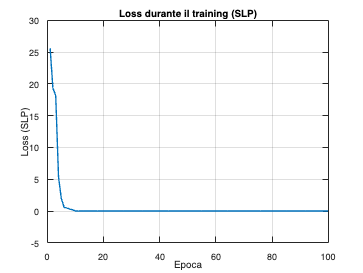


%% 10) Plot della loss
figure('Name','SLP: Loss','NumberTitle','off');
plot(1:epochs, loss_slp, 'LineWidth',1.5);
xlabel('Epoca'); ylabel('Loss (SLP)');
title('Loss durante il training (SLP)');
grid on;